Training on single CPU.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:04 |        5.59% |       1.4219 |          0.0500 |


|      50 |          50 |       00:02:09 |       75.09% |       0.4931 |          0.0500 |


|     100 |         100 |       00:04:22 |       92.35% |       0.1876 |          0.0400 |


|     150 |         150 |       00:06:33 |       94.57% |       0.1359 |          0.0400 |


|     200 |         200 |       00:08:51 |       95.69% |       0.1306 |      1.0000e-04 |


|     240 |         240 |       00:10:36 |       95.92% |       0.1223 |      1.0000e-04 |
|========================================================================================|


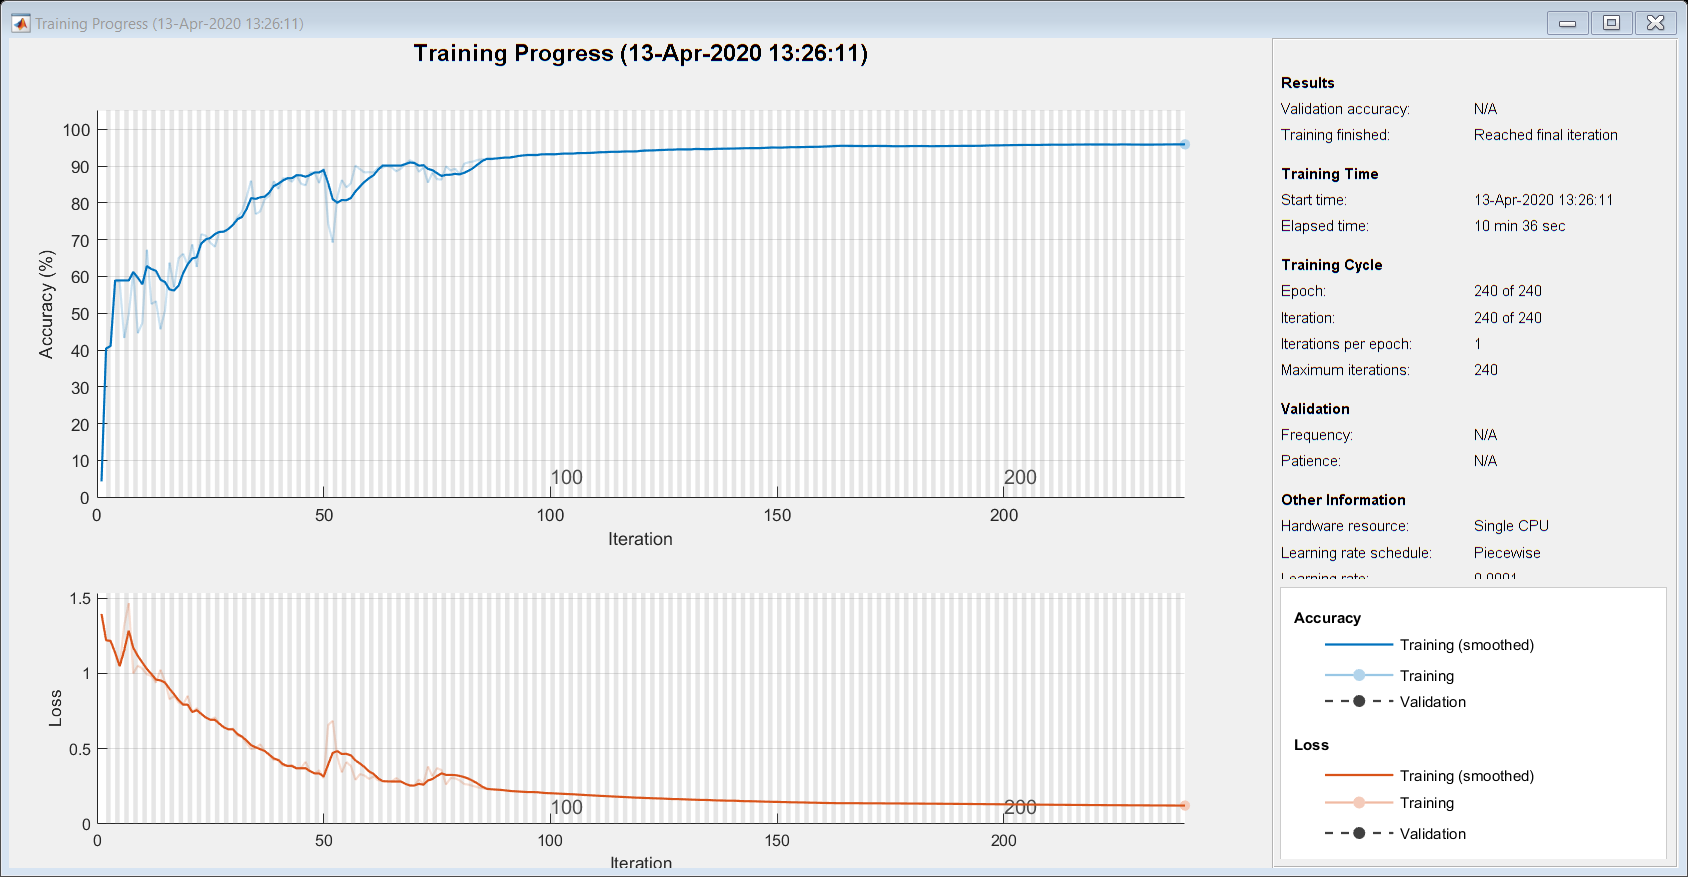

load robotDataProcessed.mat
layers = [
    sequenceInputLayer(2)
    bilstmLayer(100,'OutputMode','sequence')
    fullyConnectedLayer(4);
    softmaxLayer();
    classificationLayer()
    ];

options = trainingOptions('adam', ...
    'MaxEpochs',240, ...
    'InitialLearnRate',0.05, ...
    'GradientThreshold',1, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'LearnRateDropPeriod',80,...
    'LearnRateDropFactor',0.8,...
    'LearnRateSchedule','piecewise');

net = trainNetwork(XTrain,YTrain,layers,options);


YPred = classify(net,XTest);

accuracy = mean(YPred == YTest)

accuracy = 0.9140

confusionchart(YTest,YPred)